## 6. Compruebe mediante su modelo geométrico inverso la configuración del robot para las posturas de la herramienta halladas en el anterior laboratorio, tales como puntos de calibración.

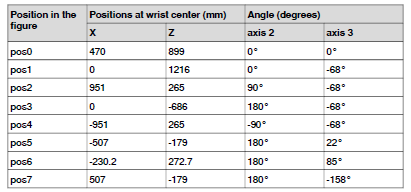

Es de considerar que los puntos de intersección dados por el fabricante solo se mueven las articulaciones 2 y 3, el resto se encuentran en posición inicial: 

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 
%Se plotea el robot, para ciertos ángulos theta.

T_0_1=L(1).A(theta_1)
T_1_2=L(2).A(theta_2);
T_1_2=[cos(theta_2-pi/2) -sin(theta_2-pi/2) 0 0
    0 0 1 0
    -sin(theta_2-pi/2) -cos(theta_2-pi/2) 0 0
    0 0 0 1]
T_2_3=L(3).A(theta_3)
T_3_4=L(4).A(theta_4);
T_3_4=[cos(theta_4) -sin(theta_4) 0 11/100
    0 0 1 47/100
    -sin(theta_4) -cos(theta_4) 0 0
    0 0 0 1]
T_4_5=L(5).A(theta_5);
T_4_5=[cos(theta_5) -sin(theta_5) 0 0
    0 0 -1 0
    sin(theta_5) cos(theta_5) 0 0
    0 0 0 1]
T_5_6=L(6).A(theta_6);
T_5_6=[cos(theta_6) -sin(theta_6) 0 2/25
    0 0 1 37/1000
    -sin(theta_6) -cos(theta_6) 0 0
    0 0 0 1]